### 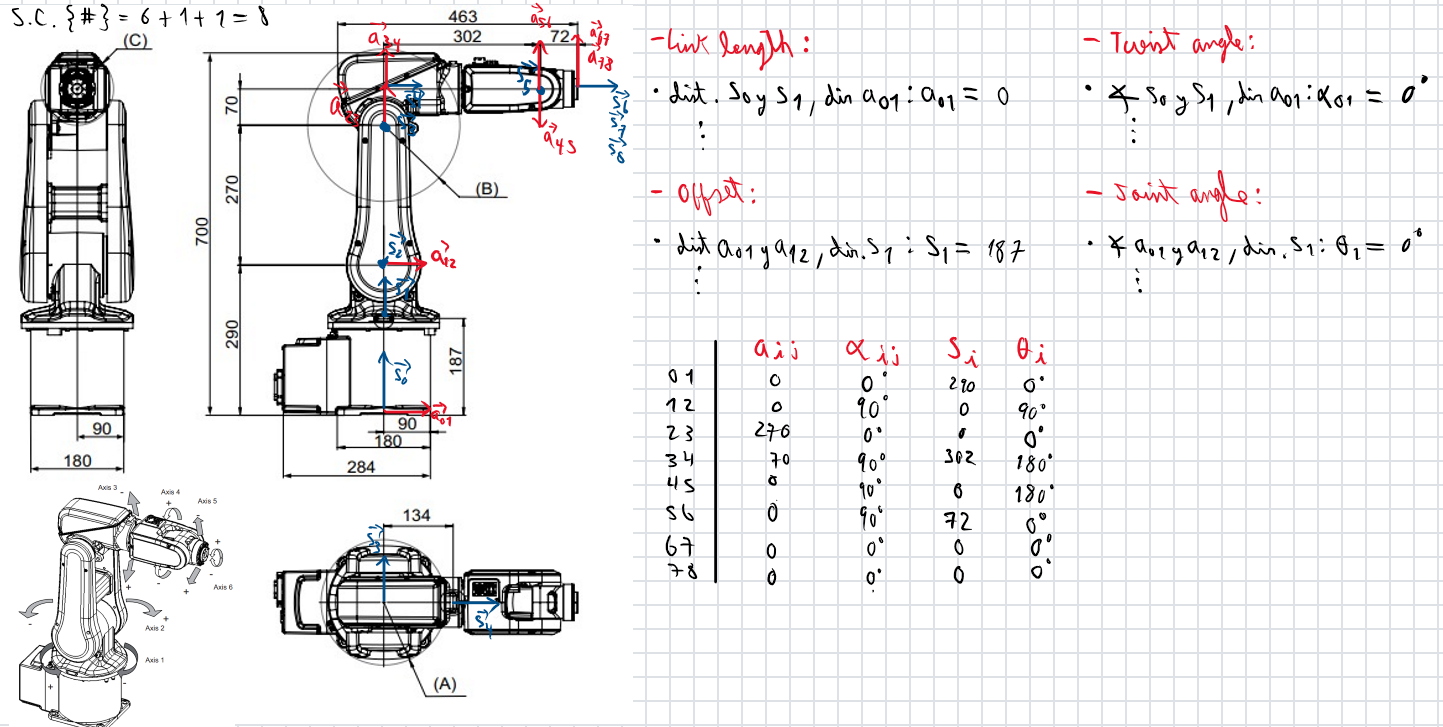 ABB IRB 120

### Parte 2: Transformación Homogénea (Home)

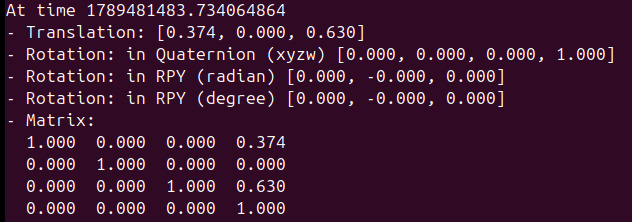 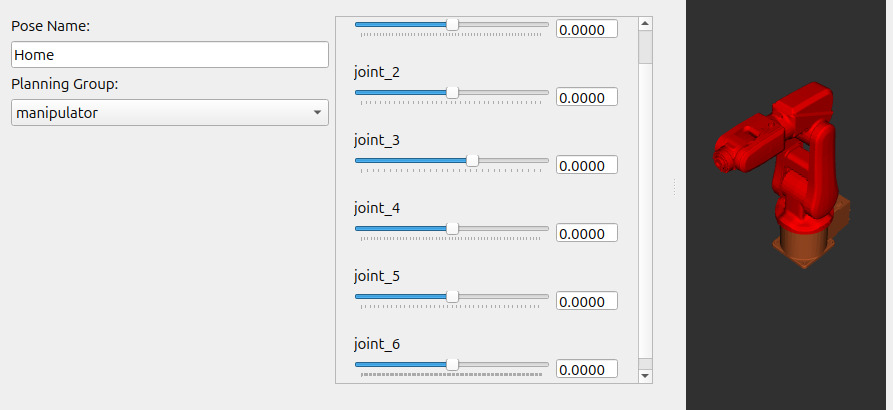

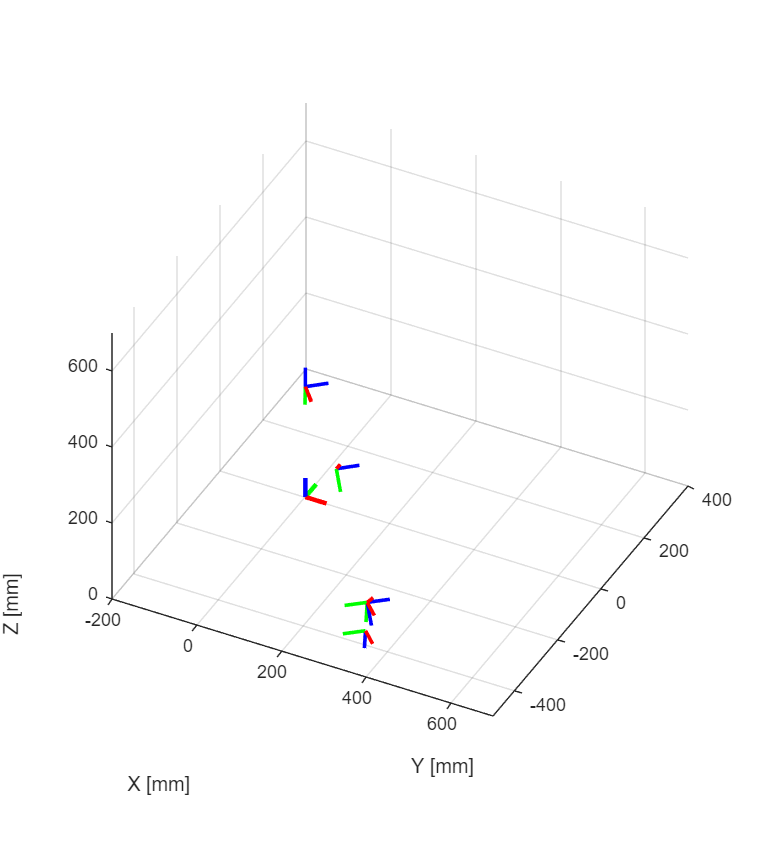

clear
close all
% Modificando los ángulos del DH, de manera que coincidan con los del xacro del robot:
DH_H = [  0,   deg2rad(0),    290, deg2rad(0);   %f1
        0,   deg2rad(-90),     0, deg2rad(-90);  %12
      270,   deg2rad(0),      0, deg2rad(0);   %23
       70,   deg2rad(-90),   302, deg2rad(0); %34
        0,   deg2rad(90),     0, deg2rad(0); %45
        0,   deg2rad(-90),    72, deg2rad(0)];   %56
figure
hold on
FKplotframes(DH_H, 0, 0)
hold off

T_H = FKplotframes(DH_H, 1, 1)

T_H = T_H(:,:,1) =

     1     0     0     0
     0     1     0     0
     0     0     1   290
     0     0     0     1


T_H(:,:,2) =

    0.0000    1.0000         0         0
   -0.0000    0.0000    1.0000         0
    1.0000   -0.0000    0.0000  290.0000
         0         0         0    1.0000


T_H(:,:,3) =

    0.0000    1.0000         0    0.0000
   -0.0000    0.0000    1.0000   -0.0000
    1.0000   -0.0000    0.0000  560.0000
         0         0         0    1.0000


T_H(:,:,4) =

    0.0000    0.0000    1.0000  302.0000
   -0.0000   -1.0000    0.0000   -0.0000
    1.0000   -0.0000   -0.0000  630.0000
         0         0         0    1.0000


T_H(:,:,5) =

    0.0000    1.0000         0  302.0000
   -0.0000         0    1.0000   -0.0000
    1.0000   -0.0000    0.0000  630.0000
         0         0         0    1.0000


T_H(:,:,6) =

    1.0000   -0.0000    0.0000  374.0000
    0.0000    1.0000   -0.0000    0.0000
   -0.0000    0.0000    1.0000  630.0000
         0         0 

### Parte 3: Cinemática inversa de las poses clave

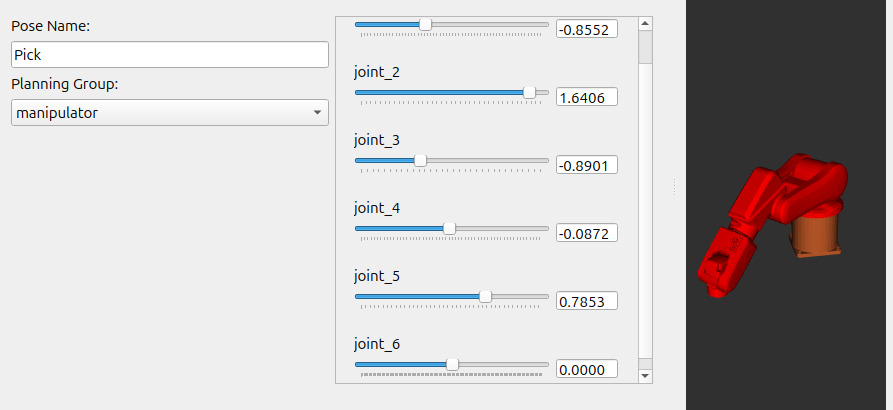 **Pick**

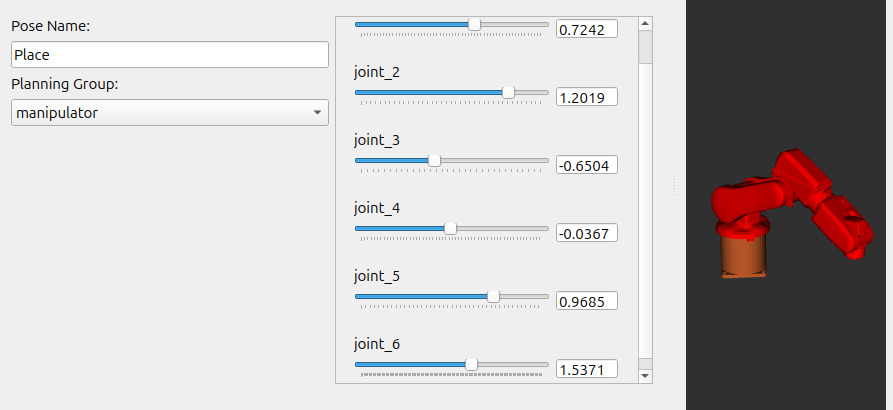 **Place**

% En Moveit, Home es el punto de referencia para medir los ángulos.
% Por tanto, para ponerlos en el DH acá, deben añadirse los ángulos dados
% por Moveit.
% Pick:
DH = [  0,   deg2rad(0),    290, -0.8552 + deg2rad(0); 
        0,   deg2rad(-90),     0, 1.6406 + deg2rad(-90);
      270,   deg2rad(0),      0, -0.8901 + deg2rad(0);
       70,   deg2rad(-90),   302, -0.0872 + deg2rad(0);
        0,   deg2rad(90),     0, 0.7853 + deg2rad(0);
        0,   deg2rad(-90),    72, 0 + deg2rad(0)];
figure;
FKplotframes(DH, 0, 0)
hold off

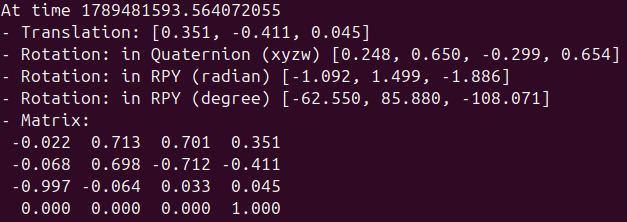

T_H_pk = FKplotframes(DH, 1, 1)

T_H_pk = T_H_pk(:,:,1) =

    0.6561    0.7547         0         0
   -0.7547    0.6561         0         0
         0         0    1.0000  290.0000
         0         0         0    1.0000


T_H_pk(:,:,2) =

    0.6545   -0.0458    0.7547         0
   -0.7529    0.0526    0.6561         0
   -0.0697   -0.9976    0.0000  290.0000
         0         0         0    1.0000


T_H_pk(:,:,3) =

    0.4474    0.4798    0.7547  176.7069
   -0.5147   -0.5519    0.6561 -203.2733
    0.7313   -0.6820    0.0000  271.1683
         0         0         0    1.0000


T_H_pk(:,:,4) =

    0.5115   -0.7129    0.4798  352.9315
   -0.4556   -0.6984   -0.5519 -405.9919
    0.7286    0.0637   -0.6820  116.3973
         0         0         0    1.0000


T_H_pk(:,:,5) =

    0.7009   -0.0223    0.7129  352.9315
   -0.7125   -0.0682    0.6984 -405.9919
    0.0330   -0.9974   -0.0637  116.3973
         0         0         0    1.0000


T_H_pk(:,:,6) =

   -0.0223    0.7129    0.7009  351.3249
   -0.0682    0.69

T_H_pk_J = FKplotframes(DH, 1, 0); %Datos originales
% Place:
DH = [  0,   deg2rad(0),    290, 0.7242 + deg2rad(0);
        0,   deg2rad(-90),     0, 1.2019 + deg2rad(-90);
      270,   deg2rad(0),      0, -0.6504 + deg2rad(0);
       70,   deg2rad(-90),   302, -0.0367 + deg2rad(0);
        0,   deg2rad(90),     0, 0.9685 + deg2rad(0);
        0,   deg2rad(-90),    72, 1.5371 + deg2rad(0)];
figure
FKplotframes(DH, 0, 0)
hold off

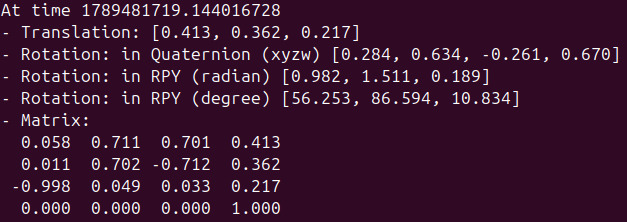

T_H_pl = FKplotframes(DH, 1, 1)

T_H_pl = T_H_pl(:,:,1) =

    0.7490   -0.6625         0         0
    0.6625    0.7490         0         0
         0         0    1.0000  290.0000
         0         0         0    1.0000


T_H_pl(:,:,2) =

    0.6986    0.2701   -0.6625         0
    0.6180    0.2389    0.7490         0
    0.3606   -0.9327    0.0000  290.0000
         0         0         0    1.0000


T_H_pl(:,:,3) =

    0.3925    0.6380   -0.6625  188.6326
    0.3471    0.5643    0.7490  166.8505
    0.8517   -0.5240    0.0000  387.3583
         0         0         0    1.0000


T_H_pl(:,:,4) =

    0.3679    0.6765    0.6380  408.7746
    0.3744   -0.7358    0.5643  361.5719
    0.8512    0.0313   -0.5240  288.7425
         0         0         0    1.0000


T_H_pl(:,:,5) =

    0.7341    0.0583   -0.6765  408.7746
    0.6771    0.0112    0.7358  361.5719
    0.0504   -0.9982   -0.0313  288.7425
         0         0         0    1.0000


T_H_pl(:,:,6) =

    0.0583    0.7109    0.7008  412.9709
    0.0112    0.70

T_H_pl_J = FKplotframes(DH, 1, 0); %Datos originales

### Parte 5: Jacobiano

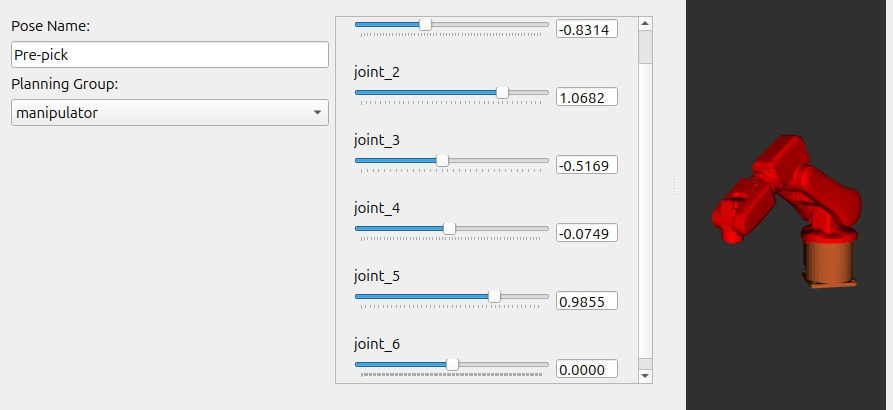  **Pre-pick**

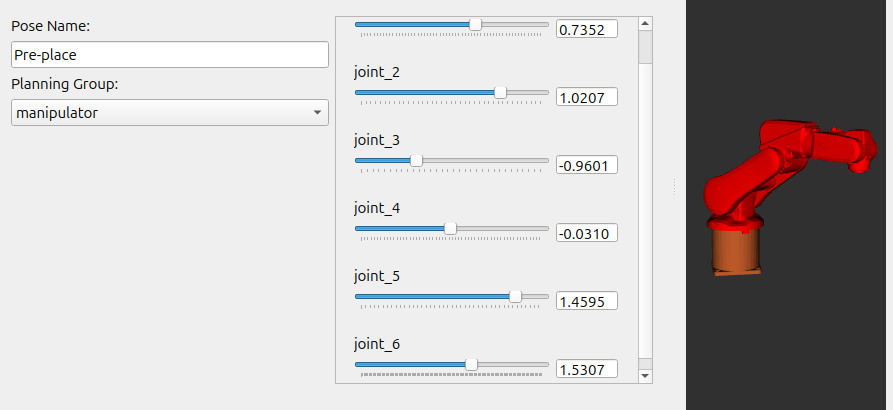 **Pre-place**

DH = [  0,   deg2rad(0),    290, -0.8314 + deg2rad(0);
        0,   deg2rad(-90),    0, 1.0682 + deg2rad(-90);
      270,   deg2rad(0),      0, -0.5169 + deg2rad(0);
       70,   deg2rad(-90),  302, -0.0749 + deg2rad(0);
        0,   deg2rad(90),     0, 0.9855 + deg2rad(0);
        0,   deg2rad(-90),   72, 0 + deg2rad(0)];
T_H_pre_pk = FKplotframes(DH, 1, 1);
T_H_pre_pk_J= FKplotframes(DH, 1, 0); %Datos originales

DH = [  0,   deg2rad(0),    290, 0.7352 + deg2rad(0);
        0,   deg2rad(-90),     0, 1.0207 + deg2rad(-90);
      270,   deg2rad(0),      0, -0.9601 + deg2rad(0);
       70,   deg2rad(-90),   302, -0.0310 + deg2rad(0);
        0,   deg2rad(90),     0, 1.4595 + deg2rad(0);
        0,   deg2rad(-90),    72, 1.5307 + deg2rad(0)];
T_H_pre_pl = FKplotframes(DH, 1, 1);
T_H_pre_pl_J = FKplotframes(DH, 1, 0); %Datos originales
% Jacobiano completo de velocidades:

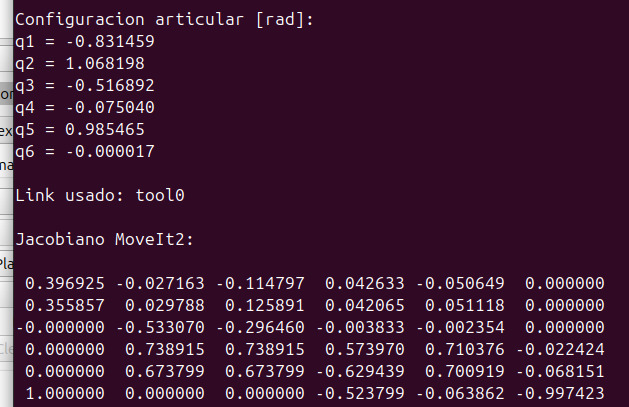

J_pre_pick = JacobianVelocities(T_H_pre_pk_J)

J_pre_pick =   396.8974  -27.1642 -114.8039   42.6345  -50.6485         0
  355.8856   29.7859  125.8837   42.0657   51.1195         0
         0 -533.0684 -296.4580   -3.8256   -2.3523         0
         0    0.7389    0.7389    0.5740    0.7104   -0.0224
         0    0.6738    0.6738   -0.6294    0.7009   -0.0680
    1.0000    0.0000    0.0000   -0.5238   -0.0637   -0.9974


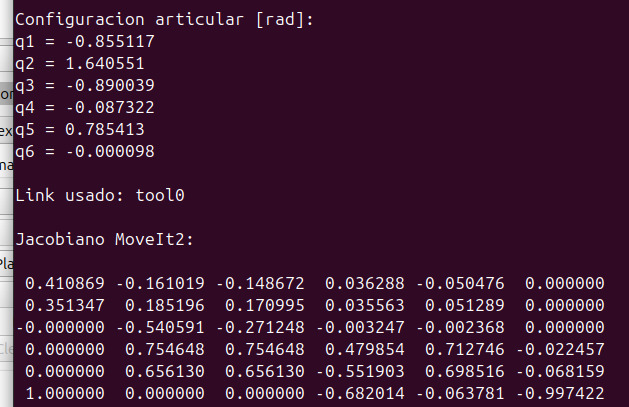

J_pick = JacobianVelocities(T_H_pk_J)

J_pick =   410.9014 -161.0102 -148.6554   36.2897  -50.4680         0
  351.3249  185.2169  171.0045   35.5533   51.2965         0
         0 -540.6010 -271.2585   -3.2424   -2.3777         0
         0    0.7547    0.7547    0.4798    0.7129   -0.0223
         0    0.6561    0.6561   -0.5519    0.6984   -0.0682
    1.0000    0.0000    0.0000   -0.6820   -0.0637   -0.9974


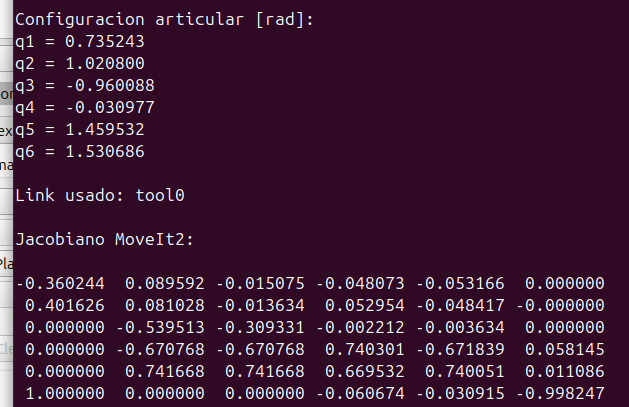

J_pre_place = JacobianVelocities(T_H_pre_pl_J)

J_pre_place =  -360.2193   89.6385  -15.0503  -48.0707  -53.1671         0
  401.6357   81.0624  -13.6103   52.9562  -48.4146         0
         0 -539.5037 -309.3357   -2.2138   -3.6447         0
         0   -0.6707   -0.6707    0.7403   -0.6718    0.0583
         0    0.7417    0.7417    0.6695    0.7401    0.0112
    1.0000    0.0000    0.0000   -0.0606   -0.0309   -0.9982


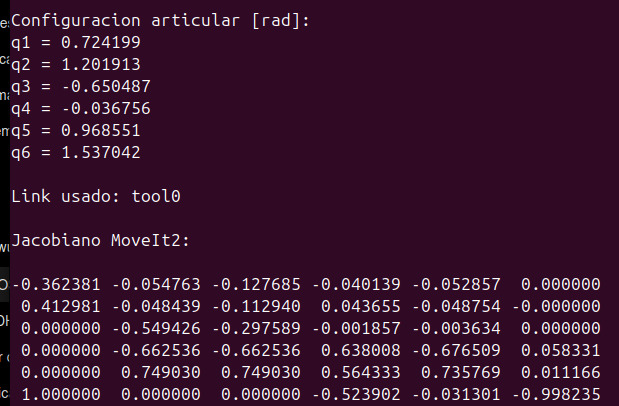

J_place = JacobianVelocities(T_H_pl_J)

J_place =  -362.3773  -54.7770 -127.7012  -40.1366  -52.8582         0
  412.9709  -48.4517 -112.9551   43.6548  -48.7526         0
         0 -549.4156 -297.5796   -1.8542   -3.6324         0
         0   -0.6625   -0.6625    0.6380   -0.6765    0.0583
         0    0.7490    0.7490    0.5643    0.7358    0.0112
    1.0000    0.0000    0.0000   -0.5240   -0.0313   -0.9982



%       Verificación con tramos 4B:
% Ida (0.2m/s):

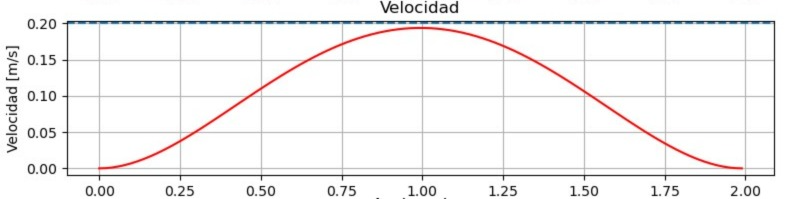 **4B, ida**

data_q = readmatrix('4B_quintico_ida_articulares.csv');
TrackVelocity(data_q, DH_H)
title('4B: ida')

% Vuelta (0.1m/s):

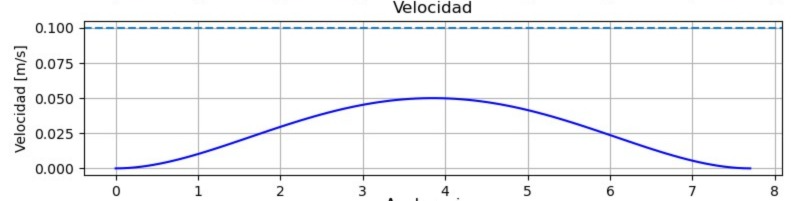 **4B, vuelta**

data_q = readmatrix('4B_quintico_vuelta_articulares.csv');
TrackVelocity(data_q, DH_H)
title('4B: vuelta')

%       Verificación con tramos 4D:
% Ida (0.2m/s):

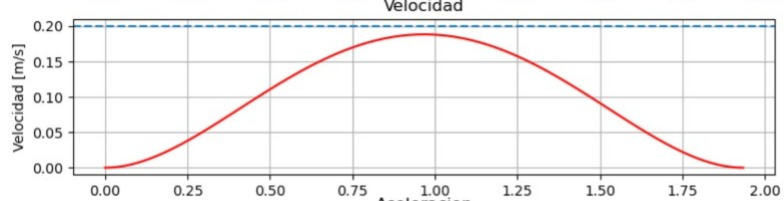 **4D, ida**

data_q = readmatrix('4D_quintico_ida_articulares.csv');
TrackVelocity(data_q, DH_H)
title('4D: ida')

% Vuelta (0.1m/s):

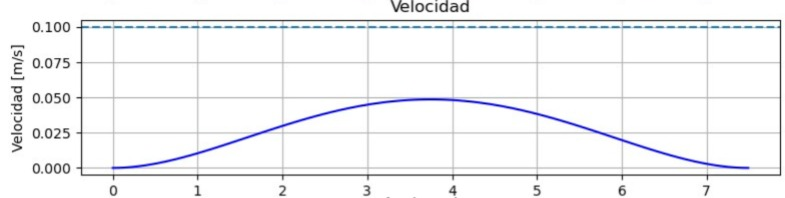 **4D, vuelta**

data_q = readmatrix('4D_quintico_vuelta_articulares.csv');
TrackVelocity(data_q, DH_H)
title('4D: vuelta')